# DynaSim/DynaLearn basic tutorial

(Single cell resting membrane potentioal example)

github@hnxj; github@dynasim

## Run this after specifying your path to dynasim.

clear;close all;clc;
PathToDynaSim = 'D:\Works\Computational'; % Change it based on your local path for dynasim
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## Single population with signle cell optimaztion examples

Call function to make a dynasim model. Modify if you want more neurons or different noise level.

## DynaSim struct 

RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS1';

spec = dsCheckSpecification('HH');
vary = {'HH','Eleak',[-70 -60 -50 -40 -30]};
solver_options = {'tspan',[0 RunDuration],'solver','rk1','dt',.01,'compile_flag',0,'verbose_flag',1};
data = dsSimulate(spec,'vary',vary,solver_options{:});


PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\solve\solve_ode_20230624092403_036.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\solve\solve_ode_20230624092403_036.m
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 1/5 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 2/5 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\par

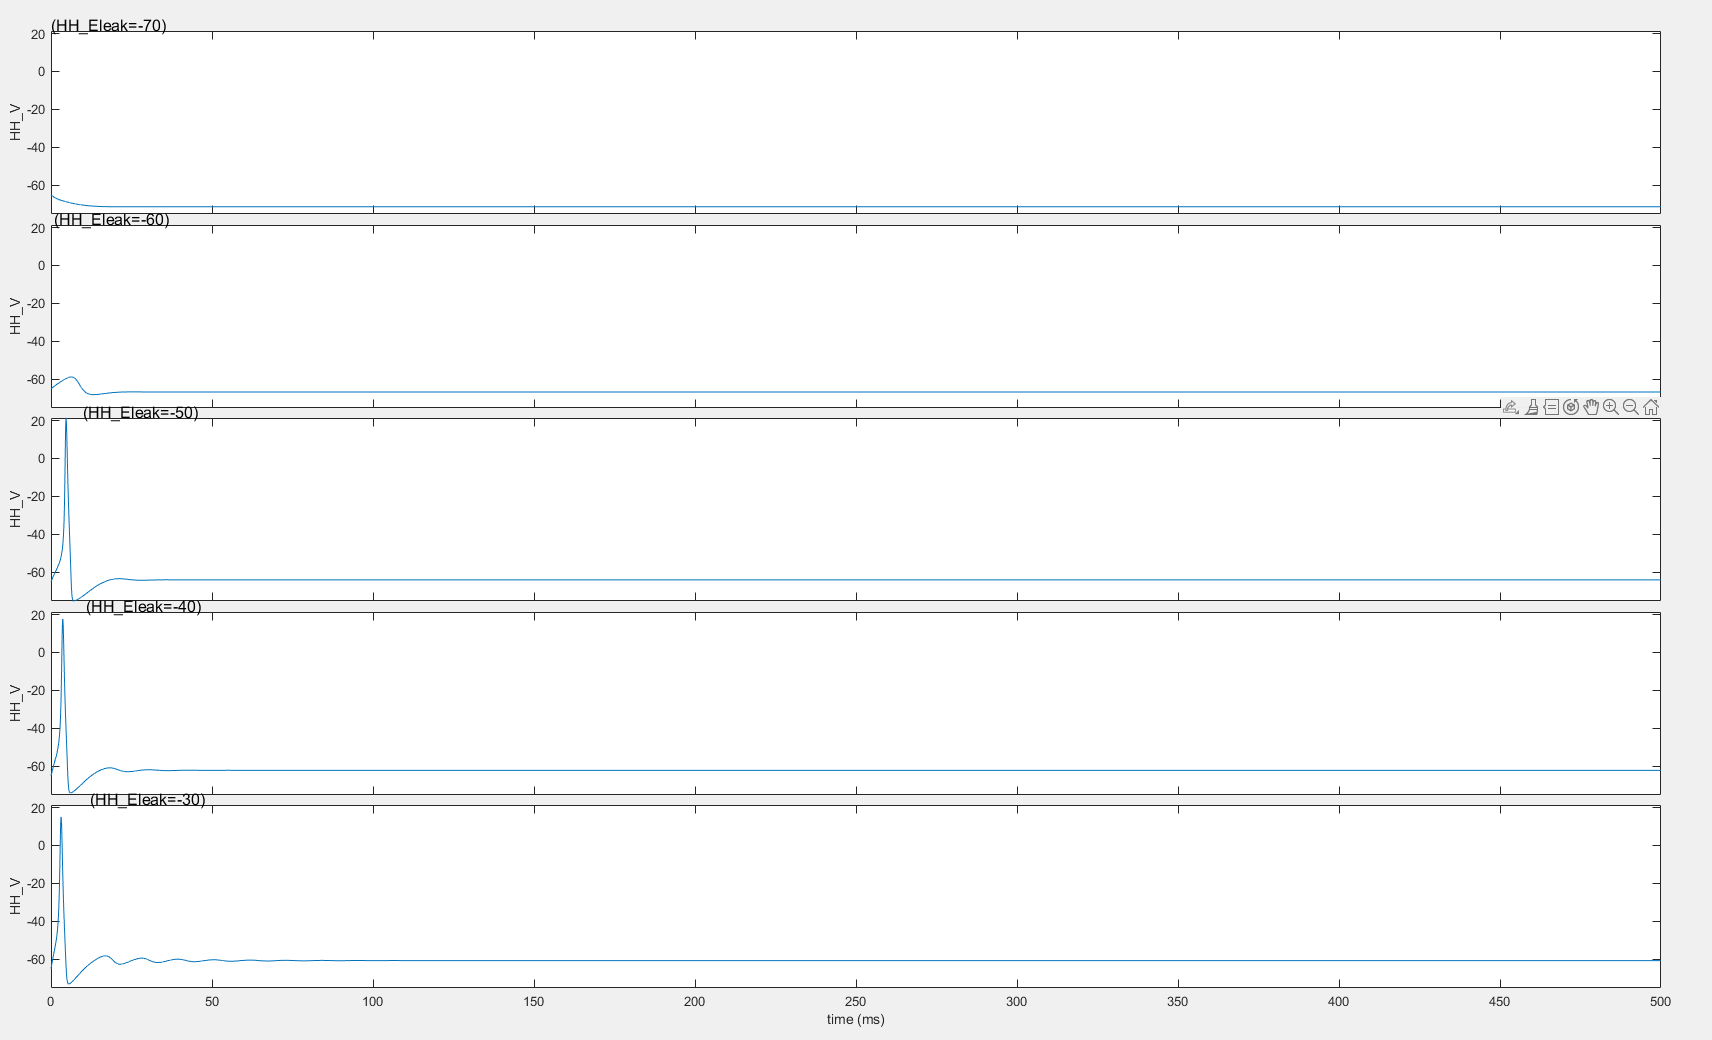

dsPlot(data,'plot_type','waveform');

## Passing to DynaLearn

dl = DynaLearn(spec, study_dir, 'raw', 'HHNS1');



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 0

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: dlModels/HHNS1

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS1\solve
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS1\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS1\solve\solve_ode_20230624092415_390.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\dlModels\HHNS1\solve\solve_ode_20230624092415_390.m
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS1\solve
Saving model parameters: D:\Works\Computational\DynaSim\dlModels\HHNS1\solve\params.mat

Running simulation 1/1 (solver='rk1', dt=0.01, tspan=[0 100]

dl.dlSave();


->Model saved in "dlModels/HHNS1/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 1; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS1 
Params.mat file loaded from dlModels/HHNS1 
--------
--->Constructing graph ... Done.

Reinitialized.


## Define optimization parameters

param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial Eleak: %g\n', p.HH_ileak_Eleak);

Initial Eleak: -54.4



target_RMP = -62;

% Define optimization parameters
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['HH', '_V'], 1, [100 RunDuration], 'av'}; % 'av' is average voltage
dlTargetParameters = {{'MQE', 1, target_RMP, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.1;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
-->No variables were manually restricted in the fitting restrict list.
--->No dynasim variables are restricted by default.
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlC

dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


dl.dlPlotAllPotentials('lfp');

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 200; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.5;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
-->No variables were manually restricted in the fitting restrict list.
--->No dynasim variables are restricted by default.
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlC

-->Log flag for loss plot is not specified; default = 1.


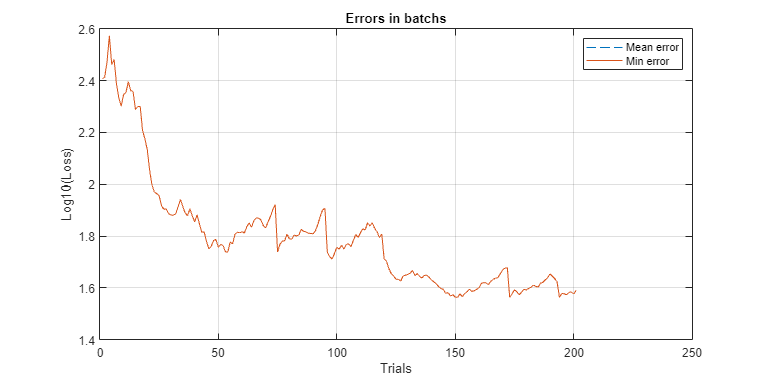


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS1/Optimal 


dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


dl.dlPlotAllPotentials('lfp');

optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Optimal Eleak: %g\n', p.HH_ileak_Eleak);

Optimal Eleak: -47.6086


## END